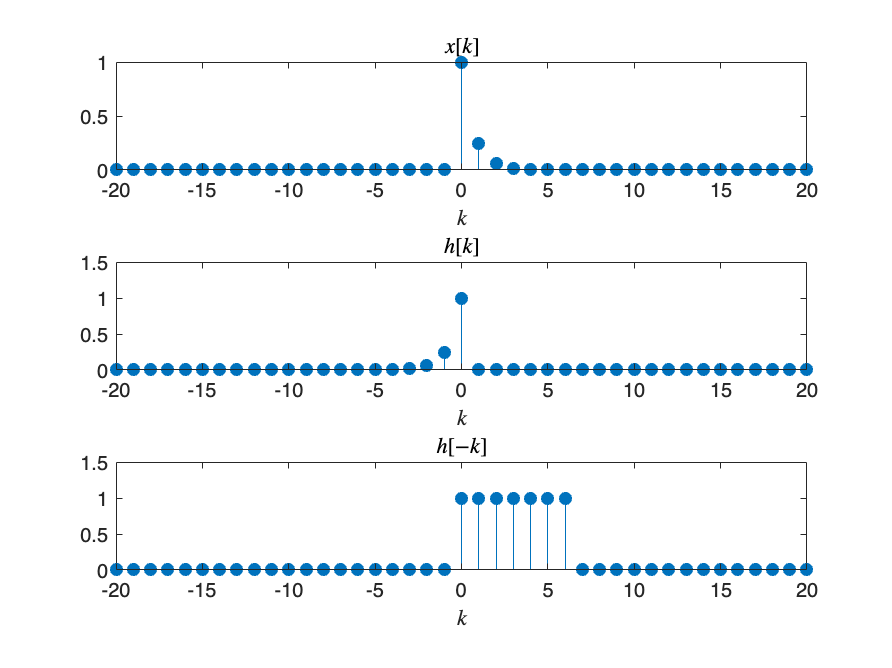

%For Example 2.2
% x[n] = a^n*u[n]
% h[n] = u[n]-u[n-N]
% h[n-k] = u[n-k]-u[n-k-N]
% Let's assume that a = 0.5 and N = 5

n = [-20:20]; % time index vector
a = 0.25; N = 7;
x_pos = 0*n; x_pos([0:20]+21) = a.^([0:20]);
k = [0:N-1];
h_pos = 0*n; h_pos(k+21) = 1; % h[k]
h_neg = 0*n; h_neg(-k+21) = 1; %h[-k]

fig = figure(1); movegui(fig,'northwest');
subplot(311); stem(n,x_pos,'filled'); xlabel('$$k$$','interpreter','latex'); title('$$x[k]$$','interpreter','latex'); axis([-20 20 0 1]);
subplot(312); stem(n,h_pos,'filled'); xlabel('$$k$$','interpreter','latex'); title('$$h[k]$$','interpreter','latex'); axis([-20 20 0 1.5]);
subplot(313); stem(n,h_neg,'filled'); xlabel('$$k$$','interpreter','latex'); title('$$h[-k]$$','interpreter','latex'); axis([-20 20 0 1.5]);

y = conv(h_pos,x_pos,'same'); % compute y[n] via convolution command
y2 = 0*n;
y2([0:N-1]+21) = (1-a.^([1:N]))./(1-a); 
y2([N:20]+21) = (a.^([N:20]-N+1)-a.^(N+1:21))./(1-a);

fig = figure(2); movegui(fig,'northwest');
subplot(211); stem(n,y,'filled'); xlabel('$$n$$','interpreter','latex'); title('$$y[n]=x[n]*h[n]$$ using $${\tt conv}$$ command','interpreter','latex'); axis([-20 20 0 3]);
subplot(212); stem(n,y2,'filled'); xlabel('$$n$$','interpreter','latex'); title('$$y[n]=x[n]*h[n]$$ computed analytically','interpreter','latex'); axis([-20 20 0 3]);

clear

% For Example 2.2b
n = [-20:20]; % time index vector
a = 0.25; N = 7;
x_pos = 0*n; x_pos([0:20]+21) = a.^([0:20]);
x_neg = 0*n; x_neg(-[0:20]+21) = a.^([0:20]);
k = [0:N-1];
h_pos = 0*n; h_pos(k+21) = 1; % h[k]
h_neg = 0*n; h_neg(-k+21) = 1; %h[-k]

fig = figure(1); movegui(fig,'northwest');
subplot(311); stem(n,x_pos,'filled'); xlabel('$$k$$','interpreter','latex'); title('$$x[k]$$','interpreter','latex'); axis([-20 20 0 1]);
subplot(312); stem(n,x_neg,'filled'); xlabel('$$k$$','interpreter','latex'); title('$$h[k]$$','interpreter','latex'); axis([-20 20 0 1.5]);
subplot(313); stem(n,h_pos,'filled'); xlabel('$$k$$','interpreter','latex'); title('$$h[-k]$$','interpreter','latex'); axis([-20 20 0 1.5]);

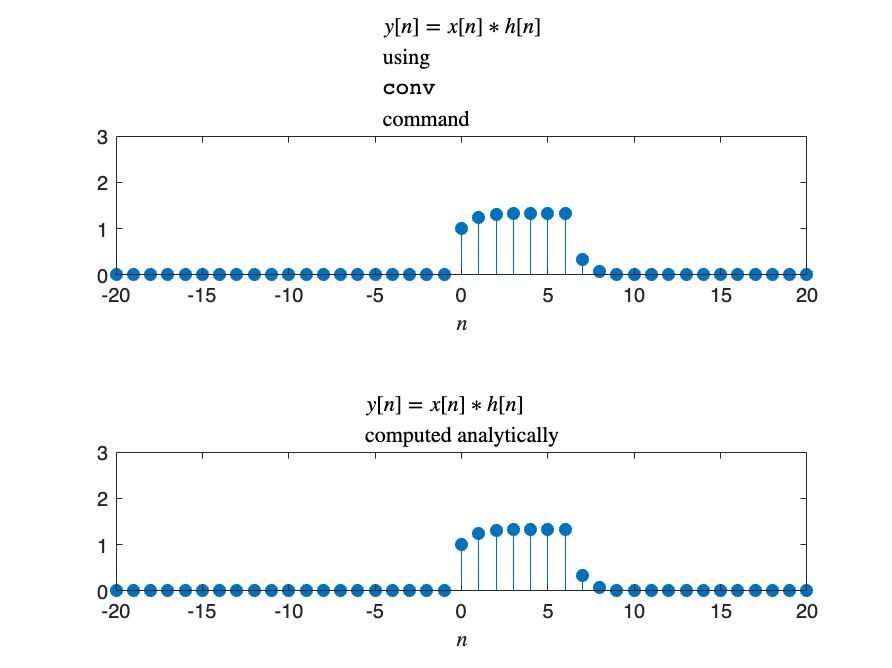


%did not finish for example 2.2B
% y = conv(h_pos,x_pos,'same'); % compute y[n] via convolution command
% y2 = 0*n;
% y2([0:N-1]+21) = (1-a.^([1:N]))./(1-a); 
% y2([N:20]+21) = (a.^([N:20]-N+1)-a.^(N+1:21))./(1-a);
% 
% fig = figure(2); movegui(fig,'northwest');
% subplot(211); stem(n,y,'filled'); xlabel('$$n$$','interpreter','latex'); title('$$y[n]=x[n]*h[n]$$ using $${\tt conv}$$ command','interpreter','latex'); axis([-20 20 0 3]);
% subplot(212); stem(n,y2,'filled'); xlabel('$$n$$','interpreter','latex'); title('$$y[n]=x[n]*h[n]$$ computed analytically','interpreter','latex'); axis([-20 20 0 3]);